# Example: Case of a regular grid with wind veering

A spatially correlated turbulent wind field is simulated with a linearly increasing yaw angle to model the wind veering.  The code is based on [1] but includes minor modification to increase the case of a regular 2D grid.

[1] Cheynet, E., Daniotti, N., Bogunović  Jakobsen, J., Snæbjörnsson, J., & Wang, J. (2022). Unfrozen Skewed  Turbulence for Wind Loading on Structures. *Applied Sciences*, *12*(19), 9537.

## Define the sampling frequency and simulation duration

clearvars;close all;clc;
addpath('./functions')
fs = 2; % sampling frequency (in Hertz) (10)
Nt = 13; % Nt is the power of 2: If M = 10, 2^M = 1024 time step (15)
[t,f] = getSamplingPara(Nt,fs); % get time and frequency vector

Duration of target time series is 1.14 hours, i.e. 4.1e+03 sec 



Nmax=numel(t); % number of time step (should be equal to 2^M)
Nfreq = numel(f); % number of frequency step (should be equal to 2^(M-1))
dt = median(diff(t)); % time step (should be equal to 1/fs)

## Define the vertices and elements of the geometry

The grid is generated perpendicular to the North, such that the wind direction will also be the wind veering. The grid is not yet regular. The grid will be regularized at the end of the simulation. 

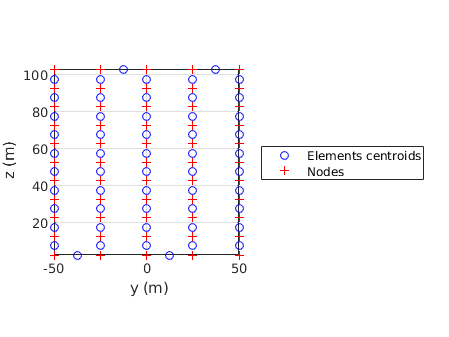

dy = 25; % lateral separation distance between two nodes in meters
dz = 10; % Vertical separation distance between two nodes in meters
minZ = 15; % lowest height above the surface in meters
Zlim = 100;% spatial extent of vertical grid above minZ in meters
Ylim = 100; % spatial extent lateral grid in meters



[geometry,minZ] = getRegularGrid(minZ,Zlim,Ylim,dy,dz);
Nyy = numel(geometry.element.X); % number of element is parametrized by Nyy


clf;close all;
figure
plot(geometry.element.Y,geometry.element.Z,'bo')
hold on
plot(geometry.node.Y,geometry.node.Z,'r+')
legend('Elements centroids','Nodes','location','eastoutside')
axis equal
grid on
xlabel(' y (m)')
ylabel(' z (m)')
axis tight

set(gcf,'color','w');


## Define the root-coherence parameters

The modified Davenport mode [1]l is the default model here. It is possible to use the modified Bown model too [2]

%  the (x,y,z) coordinate system is not the same as (X,Y,Z)!
clear CoeffDecay
CoeffDecay.Cux = [1 0]; % Modified Davenport model
CoeffDecay.Cuy = [8,  0.01]; % Modified Davenport model
CoeffDecay.Cuz = [11, 0.03]; % Modified Davenport model

CoeffDecay.Cvx = [1 0]; % Modified Davenport model
CoeffDecay.Cvy = [4 0.01]; % Modified Davenport model
CoeffDecay.Cvz = [6, 0.3]; % Modified Davenport model

CoeffDecay.Cwx = [1 0]; % Modified Davenport model
CoeffDecay.Cwy = [5, 0.4]; % Modified Davenport model
CoeffDecay.Cwz = [4, 0.2]; % Modified Davenport model


## Define the wind velocity parameters

For the sake of clarity, an excessively large wind veering is included. 

clc;clf;close all;
%%%%%%%%%%%%%%%%%%%%%%
kappa = 0.4; % von Karman constant
z0 = 0.05; % roughness height
coeffU = 118; % Coeff for Su
coeffV = 24; % Coeff for Sv
coeffW = 3.6; % Coeff for Sw
coeffUW = 12; % Coeff for Suw

% wind veering
windDirection = (90/max(geometry.element.Z(:)))*geometry.element.Z(:); %wind veering of 0.X deg per meters

Uref = 24; % Reference mean wind speed at zref
zref = 150; % Hub height
Nsamples = 1; % Number of realization at each reference wind speed
%%%%%%%%%%%%%%%%%%%%%%


## Get the target mean wind speed profile and one-point spectra

% Get the surface friction velocity from the logarithmic profile
u_star0 =  kappa*Uref./log(zref/z0);
meanU = u_star0./kappa.*log(geometry.element.Z/z0); % Mean wind speed estimated with the logarithmic profile

% meanU = 20.*ones(size(meanU));

% Get the one-point PSD at each integration point
[Su,Sv,Sw,Suw] = getTargetSpectra(meanU,u_star0,geometry,f,coeffU,coeffV,coeffW,coeffUW);


fprintf([' Duration = ',char(string(round(minutes(duration(seconds(t(end))))))), ' minutes',...
'\n min(Uref) = ',num2str(min(Uref)), ' m/s',...
'\n max(Uref) = ',num2str(max(Uref)), ' m/s',...
'\n Numel(Uref) = ',num2str(numel(Uref)),...
'\n Num. time step = ',num2str(Nmax),...
'\n fs = ',num2str(fs), ' Hz ',...
'\n zref = ',num2str(zref), ' m ',...
'\n z0 = ',num2str(z0), ' m ',...
'\n coeffU = ',num2str(coeffU),'  ',...
'\n coeffV = ',num2str(coeffV), ' ',...
'\n coeffW = ',num2str(coeffW), ' ',...
'\n coeffUW = ',num2str(coeffUW), ' ',...
'\n Target friction velocity = ',num2str(u_star0,3), ' m/s',...
'\n Nsamples = ',num2str(Nsamples), ' '])

 Duration = 68 minutes
 min(Uref) = 24 m/s
 max(Uref) = 24 m/s
 Numel(Uref) = 1
 Num. time step = 8192
 fs = 2 Hz 
 zref = 150 m 
 z0 = 0.05 m 
 coeffU = 118  
 coeffV = 24 
 coeffW = 3.6 
 coeffUW = 12 
 Target friction velocity = 1.2 m/s
 Nsamples = 1 

## Main loop to generate turbulent wind histories

rng(10) % remove this term for multiple independant realization

vx = nan(Nmax,Nyy,Nsamples);
vy = nan(Nmax,Nyy,Nsamples);
u = nan(Nmax,Nyy,Nsamples);
v = nan(Nmax,Nyy,Nsamples);
w = nan(Nmax,Nyy,Nsamples);


[u0,v0,w0,t,dx,dy,N] = windSim4D(f,Su,Sv,Sw,CoeffDecay,meanU,geometry,windDirection,'Suw',Suw);

Element no 54 is the first impacted by the wind from 6.5854 degrees 
Elapsed time is 4.255581 seconds.


u0 = bsxfun(@plus,u0,meanU');
u(1:N,:) = u0;
v(1:N,:) = v0;
w(1:N,:)  = w0;
[vx0,vy0] = WindToBridgeBase(u0,v0,windDirection,geometry.node.X,geometry.node.Y);
vx(1:N,:)  = sign(mean(vx0)).*vx0;
vy(1:N,:)  = sign(mean(vy0)).*vy0;

% Remove the time steps that are outside the time scale of the first point
% impacted by the gust
u(N+1:end,:)=[];
v(N+1:end,:)=[];
w(N+1:end,:)=[];
vx(N+1:end,:)=[];
vy(N+1:end,:)=[];   
    
meanVx = abs(mean(vx));


## Verification: Compute some integral flow characteristics

US = zeros(Nyy,1);
stdU = zeros(Nyy,1);
stdV = zeros(Nyy,1);
stdW = zeros(Nyy,1);
for ii=1:Nyy
        US(ii) = frictionVelocity(u(:,ii),v(:,ii),w(:,ii));
        stdU(ii) = std(detrend(u(:,ii),1,'omitnan'),'omitnan');
        stdV(ii) = std(detrend(v(:,ii),1,'omitnan'),'omitnan');
        stdW(ii) = std(detrend(w(:,ii),1,'omitnan'),'omitnan');

end
fprintf(['\n -----------------------------------------------------------------',...
'\n The computed friction velocity is ',num2str(median(US(:)),3),' m/s ',...
'\n Iu =  ',num2str(median(stdU(:))/mean(u(:)),3),...
'\n Iv/Iu =  ',num2str(median(stdV(:))/median(stdU(:)),3),...
'\n Iw/Iu =  ',num2str(median(stdW(:))/median(stdU(:)),3),...
'\n stdU/u_star =  ',num2str(median(stdU(:))/median(US(:)),3),...
'\n stdV/u_star =  ',num2str(median(stdV(:))/median(US(:)),3),...
'\n stdW/u_star =  ',num2str(median(stdW(:))/median(US(:)),3),...
'\n ----------------------------------------------------------------- \n\n'])


 -----------------------------------------------------------------
 The computed friction velocity is 1.19 m/s 
 Iu =  0.128
 Iv/Iu =  0.773
 Iw/Iu =  0.606
 stdU/u_star =  2.13
 stdV/u_star =  1.65
 stdW/u_star =  1.29
 ----------------------------------------------------------------- 



## Verification:  Plot the profiles of mean wind speed and standard deviation of the fluctuating components

The component vx is the velocity component perpendicular to the grid and vy is the velocity component parallel to the grid

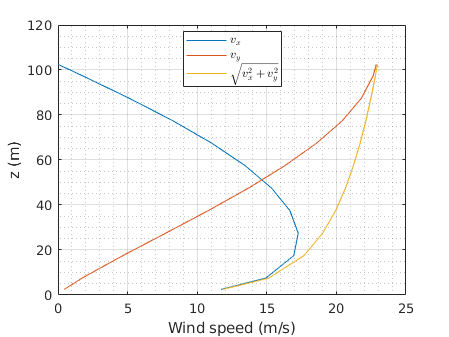

f1 = logspace(log10(1/t(end)),log10(fs/2),100);
[Su,Sv,Sw,Suw] = getTargetSpectra(meanU,u_star0,geometry,...
    f1,coeffU,coeffV,coeffW,coeffUW);

clf;close all;
figure
plot(mean(vx),geometry.element.Z)
hold on
plot(mean(vy),geometry.element.Z)
plot(mean(sqrt(vy.^2+vx.^2)),geometry.element.Z)
leg=legend('$v_x$','$v_y$','$\sqrt{v_x^2+v_y^2}$','location','best');
set(leg,'interpreter','latex');
xlabel('Wind speed (m/s)')
ylabel('z (m)')
grid on
grid minor

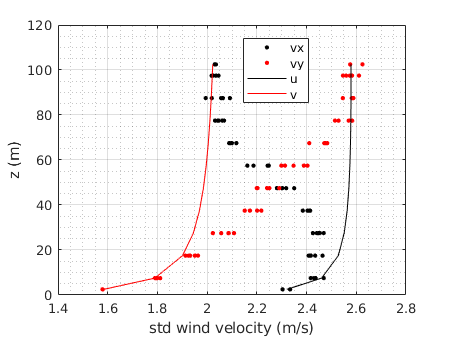


[sortedZ,indSort]= sort(geometry.element.Z,'ascend');

figure
plot(std(vx),geometry.element.Z,'k.','markersize',10)
hold on
plot(std(vy),geometry.element.Z,'r.','markersize',10)

stdU_target = sqrt(trapz(f1,Su));
stdV_target = sqrt(trapz(f1,Sv));
plot(stdU_target(indSort),sortedZ,'k','markersize',10)

plot(stdV_target(indSort),sortedZ,'r','markersize',10)

legend('vx','vy','u','v','location','best')
xlabel('std wind velocity (m/s)')
ylabel('z (m)')
grid on
grid minor

## Verification: Target vs Computed power spectral densities (wind-based coordinate system)

Case of the u v and w components

Elapsed time is 0.037298 seconds.


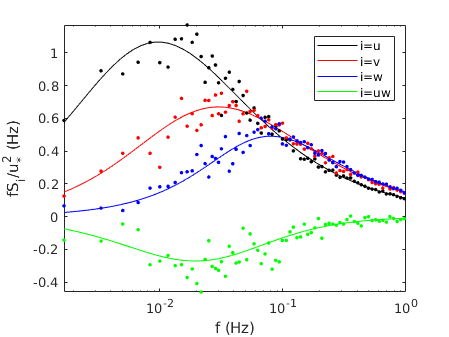

plotSpectra(meanU,u,v,w,fs,t,u_star0,geometry,coeffU,coeffV,coeffW,coeffUW)

## Verification: Target vs Computed power spectral densities  (Grid-based coordinate system)

Case of the vx, vy components at the highest altitude to see how the wind veering changes the spectra, after orojection onto the grid. vx = v and vy = u at the top of the grid if the wind direction is 90 deg.

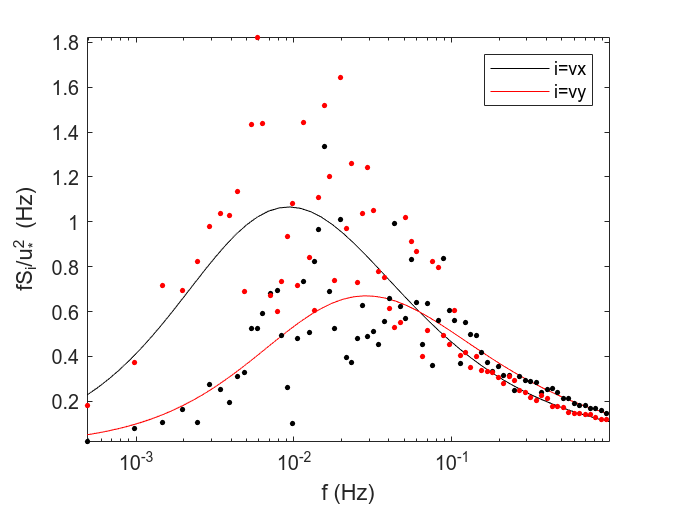

Nfft = round(numel(t)/2); % for PSD only
[~,indzMax]=max(geometry.element.Z);
[Svx,f0]=pwelch(detrend(vx(:,indzMax)),Nfft,round(Nfft/2),Nfft,fs);
[Svy,f0]=pwelch(detrend(vy(:,indzMax)),Nfft,round(Nfft/2),Nfft,fs);
f3 = logspace(log10(f0(2)*0.8),log10(f0(end)),100);
[newSvx,newF] = binAveraging(Svx,f0,f3);
[newSvy,~] = binAveraging(Svy,f0,f3);
newSvx(isnan(newF)) = [];
newSvy(isnan(newF)) = [];
newF(isnan(newF)) = [];
f1 = logspace(log10(f0(2)),log10(f0(end)),50);
[Su,Sv,Sw,Suw] = getTargetSpectra(meanU,u_star0,geometry,...
    f1,coeffU,coeffV,coeffW,coeffUW);

clf; close all;
figure
semilogx(f1,f1(:).*Su(:,indzMax)./u_star0.^2,'k',...
    f1,f1(:).*Sv(:,indzMax)./u_star0.^2,'r')
hold on; box on;
semilogx(newF,newF.*newSvx./u_star0.^2,'k.',...
    newF,newF.*newSvy./u_star0.^2,'r.','markersize',8)
xlabel('f (Hz)')
ylabel('fS_i/u^2_* (Hz)')
axis tight
set(gcf,'color','w')
legend('i=vx','i=vy')
xlim([f0(2),f0(end)])

## Save data in a regular familiar format

The lowest and maximal height are removed to obtain a regular grid. Data are reshaped into a regular gir too.

windDataName = ['windData_regular_grid.mat'];
% come back to a regular grid by removing lowest and highest heights
indTot = find(geometry.element.Z==max(geometry.element.Z) | geometry.element.Z==min(geometry.element.Z));
geometry.element.X(indTot) = [];
geometry.element.Y(indTot) = [];
geometry.element.Z(indTot) = [];

Nz = numel(unique(geometry.element.Z));

u(:,indTot) = [];
v(:,indTot) = [];
w(:,indTot) = [];
vx(:,indTot) = [];
vy(:,indTot) = [];
windDirection(indTot)= [];
Su(:,indTot)= [];
Sv(:,indTot)= [];
Sw(:,indTot)= [];
meanVx(indTot)= [];

u = reshape(u,N,Nz,[]); % whos u1
v = reshape(v,N,Nz,[]); % whos u1
w = reshape(w,N,Nz,[]);% whos w1
vx = reshape(vx,N,Nz,[]); % whos u1
vy = reshape(vy,N,Nz,[]); % whos u1


windDirection = reshape(windDirection,Nz,[]);
meanVx = reshape(meanVx,Nz,[]);
x = reshape(geometry.element.X,Nz,[]);
y = reshape(geometry.element.Y,Nz,[]);
z = reshape(geometry.element.Z,Nz,[]);

Su = reshape(Su,Nz,[]);
Sv = reshape(Sv,Nz,[]);
Sw = reshape(Sw,Nz,[]);

for ii=1:size(z,2),
    if mod(ii,2)==0
    windDirection(:,ii)=flipud(windDirection(:,ii));
    z(:,ii)=flipud(z(:,ii));
    meanVx(:,ii)=flipud(meanVx(:,ii));
    u(:,:,ii)=flip(u(:,:,ii),2);
    v(:,:,ii)=flip(v(:,:,ii),2);
    w(:,:,ii)=flip(w(:,:,ii),2);
    vx(:,:,ii)=flip(vx(:,:,ii),2);
    vy(:,:,ii)=flip(vy(:,:,ii),2);
    end
end

save(windDataName,'vx','vy','w','u','v','t',...
    'Uref','meanVx','Su','Sv','Sw','CoeffDecay','x','y','z','f','windDirection');

## Verification: Cross-covariance function analysis

Check that the time delay is properly modelled between the left and right side due to non-zero yaw angle. This is reflected by a peak of the cross-covariance at tLags > 0

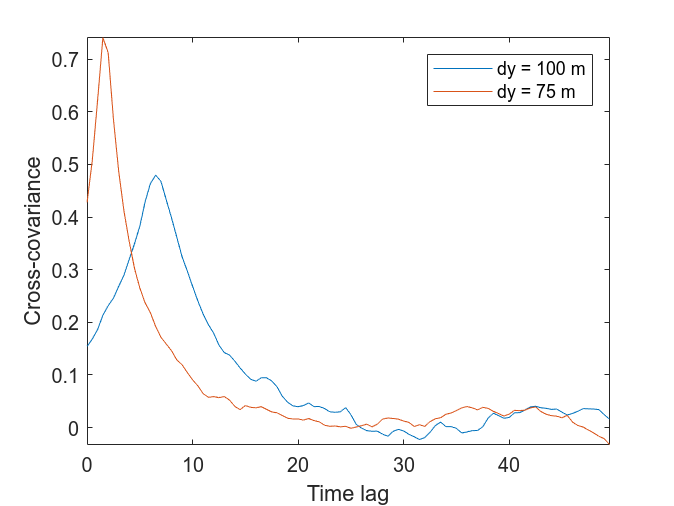

N = numel(t);
clf;close all;

[s,lags] = xcov(u(:,end,1),u(:,end,end),N,'coeff');
tLag = [lags(N+1:N+100)].*dt;
plot(tLag,s(N+1:N+100))
hold on
[s,lags] = xcov(u(:,end,1),u(:,end,end-3),N,'coeff');
tLag = [lags(N+1:N+100)].*dt;
plot(tLag,s(N+1:N+100))
legend(['dy = ',num2str(diff(y(end,[1 end]))),' m'],['dy = ',num2str(diff(y(end,[1 end-1]))),' m'])
xlabel('Time lag')
ylabel('Cross-covariance')
axis tight

## Snapshot of the turbulent field

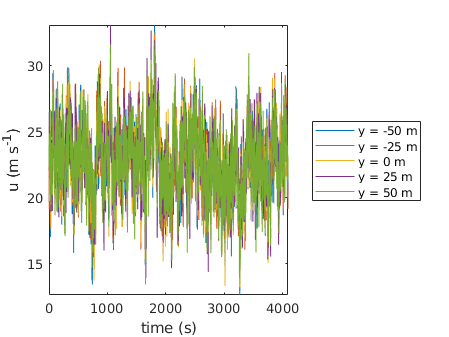

% clf;close all;
% pcolor(y,z,squeeze(u(1,:,:)));shading flat
% xlabel('y (m)')
% ylabel('z (m)')
% c =colorbar;
% ylabel(c,'u (m s^{-1})')

clf;close all;
plot(t,squeeze(u(:,1,:)));shading flat
xlabel('time (s)')
ylabel('u (m s^{-1})')
axis tight
clear leg; for ii=1:size(y,2), leg{ii} = ['y = ',num2str(y(1,ii)),' m']; end
legend(leg{:},'location','eastoutside')